clear all;close all;

% mo=load(['C:\Users\sgrc-325\Desktop\git\pipes\data\0712_0p.CSV']); %台大1.4m實測

% mo=load(['C:\Users\sgrc-325\Desktop\git\pipes\data\1118_27p.CSV']);
% mo=load(['C:\Users\sgrc-325\Desktop\git\pipes\data\1119_7p.CSV']); % power sensor at coil close to center
% mo=load(['C:\Users\sgrc-325\Desktop\git\pipes\data\1127_0p.CSV']);

mo0=load(['C:\Users\sgrc-325\Desktop\git\pipes\data\p test\1217_3P.CSV']);
mo1=load(['C:\Users\sgrc-325\Desktop\git\pipes\data\p test\1217_4P.CSV']);
mo2=load(['C:\Users\sgrc-325\Desktop\git\pipes\data\p test\1217_5P.CSV']);
mo3=load(['C:\Users\sgrc-325\Desktop\git\pipes\data\p test\1217_6P.CSV']);
mo4=load(['C:\Users\sgrc-325\Desktop\git\pipes\data\p test\1217_7P.CSV']);
mo5=load(['C:\Users\sgrc-325\Desktop\git\pipes\data\p test\1217_8P.CSV']);
mo6=load(['C:\Users\sgrc-325\Desktop\git\pipes\data\p test\1217_9P.CSV']);
mo7=load(['C:\Users\sgrc-325\Desktop\git\pipes\data\p test\1217_10P.CSV']);
mo8=load(['C:\Users\sgrc-325\Desktop\git\pipes\data\p test\1217_11P.CSV']);
mo9=load(['C:\Users\sgrc-325\Desktop\git\pipes\data\p test\1217_12P.CSV']);
mo10=load(['C:\Users\sgrc-325\Desktop\git\pipes\data\p test\1217_13P.CSV']);
mo11=load(['C:\Users\sgrc-325\Desktop\git\pipes\data\p test\1217_14P.CSV']);
mo12=load(['C:\Users\sgrc-325\Desktop\git\pipes\data\p test\1217_15P.CSV']);
mo13=load(['C:\Users\sgrc-325\Desktop\git\pipes\data\p test\1217_16P.CSV']);

mo=[mo0;mo1;mo2;mo3;mo4;mo5;mo6;mo7;mo8;mo9;mo10;mo11;mo12;mo13];


moo=mo;
% mo=moo(:,[1:17]);
% mo(1,:)=[];

[No,~]=size(moo);
t0=[1 No];
t=moo(:,1);
[a1 a3]=size(moo);
[a1 a2]=size(mo);
f=moo(:,a3); %freqency
mo_cor=zeros(a1,a2);
t=mo(:,1);

% mo_cor(:,1)=mo(:,1);
% for i=1:a1   %校正數據
%     mo_cor(i,2:4)=(Ta*Ka*(mo(i,2:4)'+Ba))';
%     mo_cor(i,5:7)=(Tg*Kg*(mo(i,5:7)'+Bg))';
%     mo_cor(i,8:10)=(Tm2a*(mo(i,8:10)'+Bm))';
%     mo_cor(i,11:13)=(Tm2a_2*(mo(i,11:13)'+Bm_2))';
% end

% acc1 = mo_cor(:,2:4);  %有校正
% gyr=mo_cor(:,5:7);
% % acc2 = mo_cor(:,5:7);
% m = mo_cor(:,8:10)*0.01;   %%%% to guess
% m2 = mo_cor(:,11:13)*0.01;   %%%%

m = mo(:,4:6); %%%% to guess
acc1 = mo(:,7:9);  %無校正
gyr1=mo(:,10:12);
lat=mo(:,13);
lon=mo(:,14);
sats=mo(:,15);
fix=mo(:,16);
hacc=mo(:,17);
vacc=mo(:,18);
tem=moo(:,19);
f=moo(:,10);
ax1=acc1(:,1);ay1=acc1(:,2);az1=acc1(:,3);
gx1=gyr1(:,1);gy1=gyr1(:,2);gz1=gyr1(:,3);
mx=m(:,1);my=m(:,2);mz=m(:,3);
aG=sqrt(ax1.^2+ay1.^2+az1.^2);
GG=sqrt(gyr1(:,1).^2+gyr1(:,2).^2+gyr1(:,3).^2);
mm4=sqrt(m(:,1).^2+m(:,2).^2+m(:,3).^2);
stdd=std(mo)'; %看標準差
stdd_cor=std(mo_cor)';

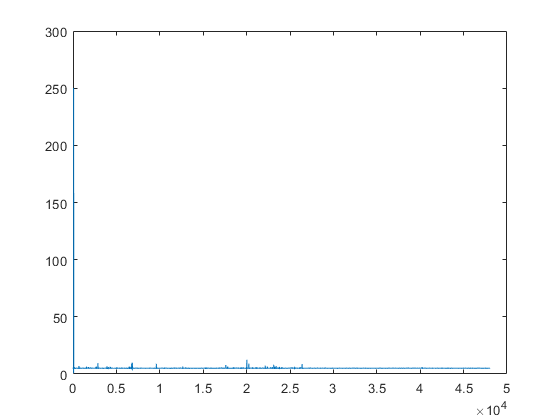

close all
figure(1)
plot(t,GG)

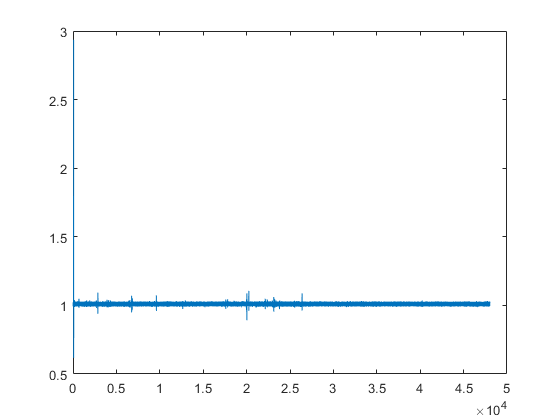


figure(2)
plot(t,aG)

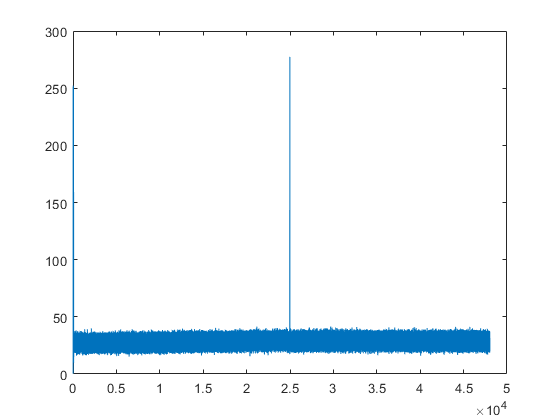


figure(2)
plot(t,mm4)

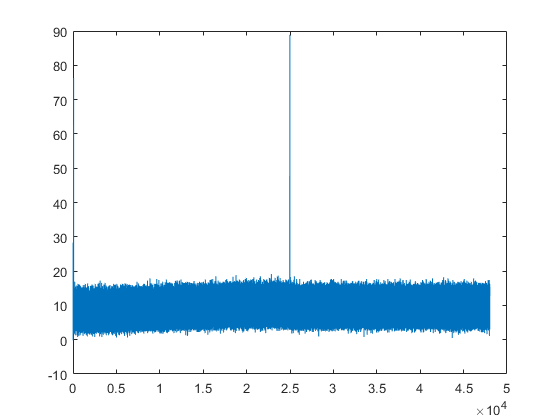


figure(4)
plot(t,m(:,1))

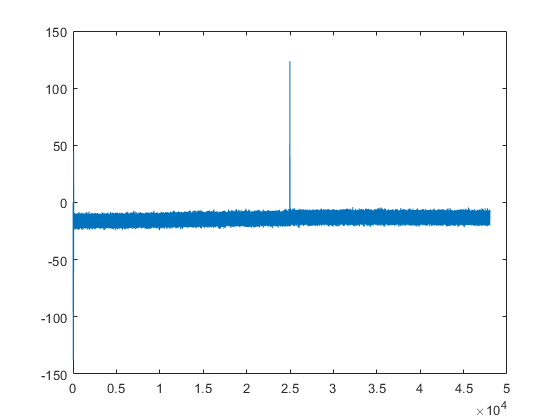

figure(5)
plot(t,m(:,2))

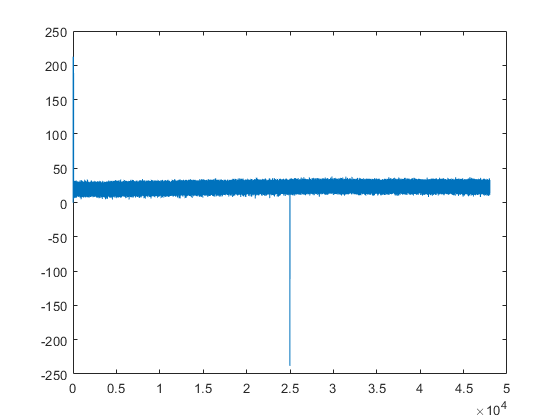

figure(6)
plot(t,m(:,3))

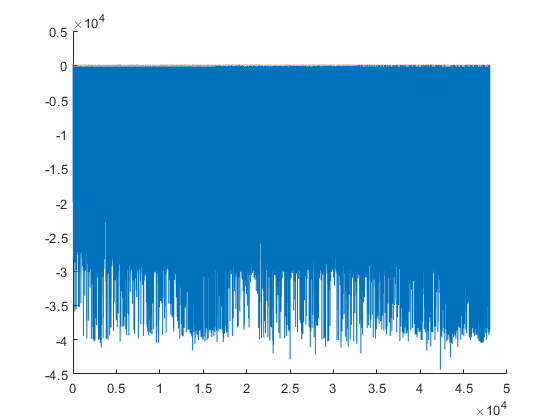

%power check dt
close all;

dt=[];dt(a1,1)=zeros;
for i=2:a1
    dt(i)=t(i)-t(i-1);
end
dt(2)=0;


hold on
% plot(t,dt)
plot(t,dt*-50000)
plot(t,m(:,3))
hold off

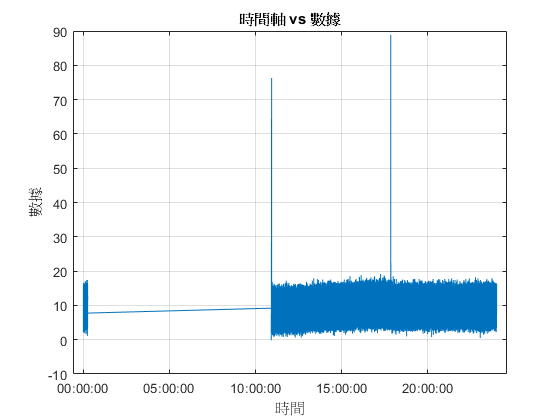

Error using xtickformat (line 34)
Invalid duration format.

% 定義檔案路徑與檔名
basePath = 'C:\Users\sgrc-325\Desktop\git\pipes\data\p test\';
fileNames = {
    '1217_3P.CSV', '1217_4P.CSV', '1217_5P.CSV', '1217_6P.CSV', ...
    '1217_7P.CSV', '1217_8P.CSV', '1217_9P.CSV', '1217_10P.CSV', ...
    '1217_11P.CSV', '1217_12P.CSV', '1217_13P.CSV', '1217_14P.CSV', ...
    '1217_15P.CSV', '1217_16P.CSV'
};

% 初始化儲存所有資料的表格
allData = [];

% 逐一讀取檔案並合併
for i = 1:length(fileNames)
    filePath = fullfile(basePath, fileNames{i});
    tempData = readtable(filePath, 'Delimiter', ',', 'ReadVariableNames', false);
    allData = [allData; tempData]; % 將每個表格資料合併
end

data=allData;

% % 讀取資料
% data = readtable('C:\Users\sgrc-325\Desktop\git\pipes\data\p test\1217_3P.CSV', 'Delimiter', ',', 'ReadVariableNames', false);

% 提取第2列與第3列（時間）
time_rtc = data.Var2;
time_gps = data.Var3;

% 如果時間列是cell格式，轉為字串
if iscell(time_rtc)
    time_rtc = string(time_rtc);
end
if iscell(time_gps)
    time_gps = string(time_gps);
end

% 使用平均值作為時間軸（或選擇其中一列作為時間軸）
time_axis = time_rtc;

% 提取第4列數據作為Y軸
y_data = data.Var4;

% 繪圖
figure;
plot(time_axis, y_data);
xlabel('時間');
ylabel('數據');
title('時間軸 vs 數據');
grid on;

% 美化X軸為 "幾點幾分幾秒" 格式
xtickformat('HH:mm:ss');